## Statistical Analysis and Plotting of TSST Data

load('All TSST Data.mat')

Error using load
All TSST Data (Nelson Truncated).mat is not found in the current folder or on the MATLAB path, but exists in:
    /Users/christopher/Documents/PTSD/NCDE Model.nosync

Change the MATLAB current folder or add its folder to the MATLAB path.

### Normality Tests

#### Nelson Data

NelsonFullMeans = [NelsonControlMeans; NelsonAtypicalMeans; NelsonMelancholicMeans; NelsonNeitherMeans]

NelsonFullMeans = 58×2 table
     ACTH     Cortisol
    ______    ________

    44.108     5.1321 
    24.789     10.836 
    17.234     6.9179 
    15.086     7.7585 
    23.042      13.18 
    44.311     6.8128 
    25.462     12.362 
    23.086     10.884 
    39.212     10.389 
    40.337     21.729 
    23.337     11.348 
    9.4742     7.7584 
    22.973     11.894 
    20.939     10.648 
    25.091     11.863 
    24.455     9.2011 


[H, p, W] = swtest(NelsonFullMeans.ACTH)

H = logical
   1


p = 1.5429e-07

W = 0.7504

[H, p, W] = swtest(log(NelsonFullMeans.ACTH))

H = logical
   1


p = 0.0116

W = 0.9439

[H, p, W] = swtest(NelsonFullMeans.Cortisol)

H = logical
   1


p = 0.0040

W = 0.9316

[H, p, W] = swtest(log(NelsonFullMeans.Cortisol))

H = logical
   0


p = 0.4538

W = 0.9819

[H, p, W] = swtest(NelsonControlMeans.Cortisol)

H = logical
   1


p = 0.0110

W = 0.8307

[H, p, W] = swtest(log(NelsonControlMeans.Cortisol))

H = logical
   0


p = 0.1735

W = 0.9212

[H, p, W] = swtest(NelsonMelancholicMeans.Cortisol)

H = logical
   0


p = 0.2036

W = 0.9216

[H, p, W] = swtest(log(NelsonMelancholicMeans.Cortisol))

H = logical
   0


p = 0.8337

W = 0.9684

[H, p, W] = swtest(NelsonAtypicalMeans.Cortisol)

H = logical
   0


p = 0.3695

W = 0.9360

[H, p, W] = swtest(log(NelsonAtypicalMeans.Cortisol))

H = logical
   0


p = 0.2833

W = 0.9277

[H, p, W] = swtest(NelsonNeitherMeans.Cortisol)

H = logical
   0


p = 0.9316

W = 0.9746

[H, p, W] = swtest(log(NelsonNeitherMeans.Cortisol))

H = logical
   0


p = 0.0594

W = 0.8826

[H, p, W] = swtest(NelsonMDDMeans.Cortisol)

H = logical
   0


p = 0.0848

W = 0.9551

[H, p, W] = swtest(log(NelsonMDDMeans.Cortisol))

H = logical
   0


p = 0.6070

W = 0.9813

[H, p, W] = swtest(NelsonControlMeans.ACTH)

H = logical
   0


p = 0.0616

W = 0.8875

[H, p, W] = swtest(log(NelsonControlMeans.ACTH))

H = logical
   0


p = 0.1321

W = 0.9129

[H, p, W] = swtest(NelsonMelancholicMeans.ACTH)

H = logical
   1


p = 0.0019

W = 0.7617

[H, p, W] = swtest(log(NelsonMelancholicMeans.ACTH))

H = logical
   0


p = 0.2135

W = 0.9274

[H, p, W] = swtest(NelsonAtypicalMeans.ACTH)

H = logical
   0


p = 0.3186

W = 0.9313

[H, p, W] = swtest(log(NelsonAtypicalMeans.ACTH))

H = logical
   0


p = 0.2694

W = 0.9262

[H, p, W] = swtest(NelsonNeitherMeans.ACTH)

H = logical
   0


p = 0.1382

W = 0.9061

[H, p, W] = swtest(log(NelsonNeitherMeans.ACTH))

H = logical
   0


p = 0.5374

W = 0.9485

[H, p, W] = swtest(NelsonMDDMeans.ACTH)

H = logical
   1


p = 1.4948e-07

W = 0.6669

[H, p, W] = swtest(log(NelsonMDDMeans.ACTH))

H = logical
   1


p = 0.0017

W = 0.8969

#### Ableson Data

[H, p, W] = swtest(AblesonControlMeans.ACTH)

H = logical
   1


p = 0.0014

W = 0.8781

[H, p, W] = swtest(log(AblesonControlMeans.ACTH))

H = logical
   1


p = 0.0314

W = 0.9347

% Unfortunately neither log nor sqrt transformation can this normal
[H, p, W] = swtest(sqrt(AblesonControlMeans.ACTH))

H = logical
   1


p = 0.0088

W = 0.9165

[H, p, W] = swtest(AblesonControlMeans.Cortisol)

H = logical
   1


p = 0.0478

W = 0.9405

[H, p, W] = swtest(log(AblesonControlMeans.Cortisol))

H = logical
   1


p = 0.0355

W = 0.9364

% Log-transformation didn't make it normal, but sqrt does
[H, p, W] = swtest(sqrt(AblesonControlMeans.Cortisol))

H = logical
   0


p = 0.0531

W = 0.9419

[H, p, W] = swtest(AblesonMDDMeans.ACTH)

H = logical
   0


p = 0.2038

W = 0.9134

[H, p, W] = swtest(log(AblesonMDDMeans.ACTH))

H = logical
   0


p = 0.8621

W = 0.9674

% Sqrt works here too, which is good because we need to compare Ableson
% Control and MDD
[H, p, W] = swtest(sqrt(AblesonMDDMeans.ACTH))

H = logical
   0


p = 0.5672

W = 0.9479

[H, p, W] = swtest(AblesonMDDMeans.Cortisol)

H = logical
   0


p = 0.1330

W = 0.9043

[H, p, W] = swtest(log(AblesonMDDMeans.Cortisol))

H = logical
   0


p = 0.6556

W = 0.9537

[H, p, W] = swtest(sqrt(AblesonMDDMeans.Cortisol))

H = logical
   0


p = 0.5010

W = 0.9433

#### Full Population Means

[H, p, W] = swtest(FullPopControlMeans.Cortisol)

H = logical
   1


p = 0.0220

W = 0.9461

[H, p, W] = swtest(log(FullPopControlMeans.Cortisol))

H = logical
   0


p = 0.2146

W = 0.9702

[H, p, W] = swtest(FullPopControlMeans.ACTH)

H = logical
   1


p = 0.0056

W = 0.9291

[H, p, W] = swtest(log(FullPopControlMeans.ACTH))

H = logical
   0


p = 0.1629

W = 0.9674

## t-tests

#### ACTH Means

[H, p, CI] = ttest2(FullPopControlMeans.ACTH, FullPopMDDMeans.ACTH)

H = 0

p = 0.9410

CI =    -4.4941
    4.1698


% This is likely invalid due to small sample size of Nelson Control and
% Nelson MDD Means not being normal or log-normal
[H, p, CI] = ttest2(NelsonControlMeans.ACTH, NelsonMDDMeans.ACTH)

H = 0

p = 0.6241

CI =    -5.4524
    9.0107


[H, p, CI] = ttest2(log(NelsonControlMeans.ACTH), log(NelsonAtypicalMeans.ACTH))

H = 0

p = 0.0689

CI =    -0.0198
    0.4970


[H, p, CI] = ttest2(log(NelsonControlMeans.ACTH), log(NelsonMelancholicMeans.ACTH))

H = 0

p = 0.4077

CI =    -0.4713
    0.1970


[H, p, CI] = ttest2(log(NelsonControlMeans.ACTH), log(NelsonNeitherMeans.ACTH))

H = 0

p = 0.3426

CI =    -0.1438
    0.3996


% Unfortunately, Ableson Control Means ACTH cannot be made normal and the
% sample size is too small for the CLT to apply
[H, p, CI] = ttest2(log(AblesonControlMeans.ACTH), log(AblesonMDDMeans.ACTH))

H = 0

p = 0.4704

CI =    -0.1876
    0.4004


**Here, we find no significant difference between any of the sets after log-transformation.**

#### Cortisol Means

[H, p, CI] = ttest2(FullPopControlMeans.Cortisol, FullPopMDDMeans.Cortisol)

H = 1

p = 0.0088

CI =     0.4391
    2.9694


[H, p, CI] = ttest2(log(NelsonControlMeans.Cortisol), log(NelsonMDDMeans.Cortisol))

H = 1

p = 0.0139

CI =     0.0614
    0.5190


[H, p, CI] = ttest2(log(NelsonControlMeans.Cortisol), log(NelsonAtypicalMeans.Cortisol))

H = 1

p = 0.0106

CI =     0.0940
    0.6495


[H, p, CI] = ttest2(log(NelsonControlMeans.Cortisol), log(NelsonMelancholicMeans.Cortisol))

H = 0

p = 0.3648

CI =    -0.1474
    0.3883


[H, p, CI] = ttest2(log(NelsonControlMeans.Cortisol), log(NelsonNeitherMeans.Cortisol))

H = 1

p = 0.0080

CI =     0.1108
    0.6701


[H, p, CI] = ttest2(sqrt(AblesonControlMeans.Cortisol), sqrt(AblesonMDDMeans.Cortisol))

H = 0

p = 0.8956

CI =    -0.3145
    0.3586


**Here, we find statistically significant difference between Nelson Control and (Nelson MDD, Atypical, Neither) mean cortisol concentrations. We also have significant difference between Control and MDD for the Nelson+Ableson full dataset. However, Nelson Control vs Nelson Melancholic and Ableson Control vs Ableson MDD fall far short of statistical significance.**

#### ACTH Ranges

[H, p, CI] = ttest2(FullPopControlRanges.ACTH, FullPopMDDRanges.ACTH)

H = 0

p = 0.7604

W =   -10.2215
    7.4903


[H, p, CI] = ttest2(log(NelsonControlRanges.ACTH), log(NelsonMDDRanges.ACTH))

H = 0

p = 0.3109

W =    -7.8087
   24.0921


[H, p, CI] = ttest2(log(NelsonControlRanges.ACTH), log(NelsonAtypicalRanges.ACTH))

H = 1

p = 0.0182

W =     3.4378
   33.8955


[H, p, CI] = ttest2(log(NelsonControlRanges.ACTH), log(NelsonMelancholicRanges.ACTH))

H = 0

p = 0.6275

W =   -30.1926
   18.5227


[H, p, CI] = ttest2(log(NelsonControlRanges.ACTH), log(NelsonNeitherRanges.ACTH))

H = 0

p = 0.1158

W =    -3.3094
   28.4927


[H, p, CI] = ttest2(AblesonControlRanges.ACTH, AblesonMDDRanges.ACTH)

H = 0

p = 0.5298

W =    -7.2178
   13.8502


**We only find statistically significant difference between Nelson Control and Atypical MDD ACTH (this time for the range, rather than mean).**

#### Cortisol Ranges

[H, p, CI] = ttest2(FullPopControlRanges.Cortisol, FullPopMDDRanges.Cortisol)

H = 0

p = 0.7204

CI =    -2.5242
    1.7505


[H, p, CI] = ttest2(log(NelsonControlRanges.Cortisol), log(NelsonMDDRanges.Cortisol))

H = 0

p = 0.1169

CI =    -0.0683
    0.5975


[H, p, CI] = ttest2(log(NelsonControlRanges.Cortisol), log(NelsonAtypicalRanges.Cortisol))

H = 1

p = 0.0246

CI =     0.0609
    0.8198


[H, p, CI] = ttest2(log(NelsonControlRanges.Cortisol), log(NelsonMelancholicRanges.Cortisol))

H = 0

p = 0.9329

CI =    -0.4122
    0.3794


[H, p, CI] = ttest2(log(NelsonControlRanges.Cortisol), log(NelsonNeitherRanges.Cortisol))

H = 0

p = 0.0551

CI =    -0.0091
    0.7890


[H, p, CI] = ttest2(AblesonControlRanges.Cortisol, AblesonMDDRanges.Cortisol)

H = 0

p = 0.8718

CI =    -2.2502
    2.6453


**Significance only between Control and Atypical Cortisol ranges.**

#### ACTH Minimums

[H, p, CI] = ttest2(FullPopControlMins.ACTH, FullPopMDDMins.ACTH)

H = 0

p = 0.6192

CI =    -1.5781
    2.6382


[H, p, CI] = ttest2(log(NelsonControlMins.ACTH), log(NelsonMDDMins.ACTH))

H = 0

p = 0.4455

CI =    -0.2637
    0.1175


[H, p, CI] = ttest2(log(NelsonControlMins.ACTH), log(NelsonAtypicalMins.ACTH))

H = 0

p = 0.8304

CI =    -0.2364
    0.2921


[H, p, CI] = ttest2(log(NelsonControlMins.ACTH), log(NelsonMelancholicMins.ACTH))

H = 0

p = 0.1439

CI =    -0.4459
    0.0684


[H, p, CI] = ttest2(log(NelsonControlMins.ACTH), log(NelsonNeitherMins.ACTH))

H = 0

p = 0.6861

CI =    -0.3022
    0.2019


[H, p, CI] = ttest2(AblesonControlMins.ACTH, AblesonMDDMins.ACTH)

H = 0

p = 0.0861

CI =    -0.5020
    7.3208


**Again, no statistical significance, this time for minimum ACTH values.**

#### Cortisol Minimums

[H, p, CI] = ttest2(FullPopControlMins.Cortisol, FullPopMDDMins.Cortisol)

H = 1

p = 5.8667e-05

W =     0.8873
    2.4836


[H, p, CI] = ttest2(NelsonControlMins.Cortisol, NelsonMDDMins.Cortisol)

H = 1

p = 0.0062

W =     0.4660
    2.6898


[H, p, CI] = ttest2(NelsonControlMins.Cortisol, NelsonAtypicalMins.Cortisol)

H = 1

p = 0.0147

W =     0.3750
    3.1430


[H, p, CI] = ttest2(NelsonControlMins.Cortisol, NelsonMelancholicMins.Cortisol)

H = 0

p = 0.1808

W =    -0.5218
    2.6418


[H, p, CI] = ttest2(NelsonControlMins.Cortisol, NelsonNeitherMins.Cortisol)

H = 1

p = 0.0110

W =     0.4854
    3.4179


[H, p, CI] = ttest2(AblesonControlMins.Cortisol, AblesonMDDMins.Cortisol)

H = 0

p = 0.8384

W =    -1.2076
    1.4819


**Cortisol Minimums are significantly different for Nelson Control vs (MDD, Atypical, Neither), the same groups that we had significant difference in cortisol means. Also, the full population with Ableson+Nelson data shows significant difference in Cortisol minimums.**

#### ACTH Maximums

[H, p, CI] = ttest2(FullPopControlMaxes.ACTH, FullPopMDDMaxes.ACTH)

H = 0

p = 0.8639

W =   -10.4781
    8.8070


[H, p, CI] = ttest2(NelsonControlMaxes.ACTH, NelsonMDDMaxes.ACTH)

H = 0

p = 0.3804

W =    -9.5497
   24.6391


[H, p, CI] = ttest2(NelsonControlMaxes.ACTH, NelsonAtypicalMaxes.ACTH)

H = 1

p = 0.0198

W =     3.3580
   35.8087


[H, p, CI] = ttest2(NelsonControlMaxes.ACTH, NelsonMelancholicMaxes.ACTH)

H = 0

p = 0.5201

W =   -34.4033
   17.8032


[H, p, CI] = ttest2(NelsonControlMaxes.ACTH, NelsonNeitherMaxes.ACTH)

H = 0

p = 0.1526

W =    -4.9174
   29.8825


[H, p, CI] = ttest2(AblesonControlMaxes.ACTH, AblesonMDDMaxes.ACTH)

H = 0

p = 0.2662

W =    -5.2942
   18.7453


**We only have significance for Nelson Control vs Atypical for ACTH Maximums.**

#### Cortisol Maximums

[H, p, CI] = ttest2(FullPopControlMaxes.Cortisol, FullPopMDDMaxes.Cortisol)

H = 0

p = 0.2835

W =    -1.0898
    3.6870


[H, p, CI] = ttest2(NelsonControlMaxes.Cortisol, NelsonMDDMaxes.Cortisol)

H = 1

p = 0.0445

W =     0.1109
    8.5682


[H, p, CI] = ttest2(NelsonControlMaxes.Cortisol, NelsonAtypicalMaxes.Cortisol)

H = 1

p = 0.0185

W =     1.1823
   11.8565


[H, p, CI] = ttest2(NelsonControlMaxes.Cortisol, NelsonMelancholicMaxes.Cortisol)

H = 0

p = 0.8476

W =    -5.5439
    6.7041


[H, p, CI] = ttest2(NelsonControlMaxes.Cortisol, NelsonNeitherMaxes.Cortisol)

H = 1

p = 0.0264

W =     0.7810
   11.5942


[H, p, CI] = ttest2(AblesonControlMaxes.Cortisol, AblesonMDDMaxes.Cortisol)

H = 0

p = 0.8340

W =    -2.8579
    3.5273


**Again, we have significance between Nelson Control and (MDD, Atypical, Neither), this time for Cortisol maximums.**

## Nelson vs Ableson

#### ACTH Means

[H, p, CI] = ttest2(AblesonControlMeans.ACTH, NelsonControlMeans.ACTH)

H = 0

p = 0.1738

W =   -11.1205
    2.0642


[H, p, CI] = ttest2(AblesonMDDMeans.ACTH, NelsonMDDMeans.ACTH)

H = 0

p = 0.1416

W =   -12.9319
    1.8982


**No statistical significance between ACTH means.**

#### Cortisol Means

[H, p, CI] = ttest2(AblesonControlMeans.Cortisol, NelsonControlMeans.Cortisol)

H = 0

p = 0.5773

W = 2×1
   -2.6327
    1.4831


[H, p, CI] = ttest2(AblesonMDDMeans.Cortisol, NelsonMDDMeans.Cortisol)

H = 0

p = 0.0666

W = 2×1
   -0.1359
    3.9637


**No significance for Cortisol mean difference (although the MDD groups are close).**

#### ACTH Ranges

[H, p, CI] = ttest2(AblesonControlRanges.ACTH, NelsonControlRanges.ACTH)

H = 1

p = 0.0067

W = 2×1
  -29.9069
   -5.0834


[H, p, CI] = ttest2(AblesonMDDRanges.ACTH, NelsonMDDRanges.ACTH)

H = 0

p = 0.1047

W = 2×1
  -28.0635
    2.7242


**The 2 control groups are significantly different in ACTH ranges.**

#### Cortisol Ranges

[H, p, CI] = ttest2(AblesonControlRanges.Cortisol, NelsonControlRanges.Cortisol)

H = 1

p = 0.0022

W = 2×1
   -8.6420
   -2.0100


[H, p, CI] = ttest2(AblesonMDDRanges.Cortisol, NelsonMDDRanges.Cortisol)

H = 0

p = 0.1023

W = 2×1
   -6.0931
    0.5694


**Also, the 2 control groups are significantly different in cortisol ranges.**

#### ACTH Minimums

[H, p, CI] = ttest2(AblesonControlMins.ACTH, NelsonControlMins.ACTH)

H = 0

p = 0.8387

W = 2×1
   -3.6215
    4.4433


[H, p, CI] = ttest2(AblesonMDDMins.ACTH, NelsonMDDMins.ACTH)

H = 1

p = 0.0090

W = 2×1
   -6.2568
   -0.9342


**We have significant difference between the MDD groups for ACTH minimums.**

#### Cortisol Minimums

[H, p, CI] = ttest2(AblesonControlMins.Cortisol, NelsonControlMins.Cortisol)

H = 0

p = 0.1424

W = 2×1
   -0.3205
    2.1647


[H, p, CI] = ttest2(AblesonMDDMins.Cortisol, NelsonMDDMins.Cortisol)

H = 1

p = 2.3836e-04

W = 2×1
    1.1595
    3.5661


**And also for Cortisol minimums.**

#### ACTH Maximums

[H, p, CI] = ttest2(AblesonControlMaxes.ACTH, NelsonControlMaxes.ACTH)

H = 1

p = 0.0172

W = 2×1
  -31.0107
   -3.1578


[H, p, CI] = ttest2(AblesonMDDMaxes.ACTH, NelsonMDDMaxes.ACTH)

H = 0

p = 0.0522

W = 2×1
  -32.6940
    0.1637


**ACTH Maximum is significantly different between the control groups, and only off by 0.0022 from significance for the MDD groups.**

#### Cortisol Maximums

[H, p, CI] = ttest2(AblesonControlMaxes.Cortisol, NelsonControlMaxes.Cortisol)

H = 1

p = 0.0239

W = 2×1
   -8.2010
   -0.6069


[H, p, CI] = ttest2(AblesonMDDMaxes.Cortisol, NelsonMDDMaxes.Cortisol)

H = 0

p = 0.8379

W = 2×1
   -4.2918
    3.4936


**We have statistically significant difference between the control groups for Cortisol maximums.**

## Significance Summary

We found significance evidence for a difference in population Cortisol mean, minimum and maximum between Nelson Control and Nelson Atypical, Neither and all Nelson MDD.

We also found evidence for difference between Nelson Control and Nelson Atypical for ACTH mean, maximum and range.

This seems to suggest that there is no difference between Nelson Control and Nelson Melancholic in terms of ACTH and Cortisol concentrations. 

For the full population with Nelson and Ableson data, we found significant differences between Control and MDD only for Cortisol mean and minimums. This implies that classification with only cortisol time series as input should have done better, so I'm not sure why it didn't in practice.

Between Nelson and Ableson data, we have statistical significance between the Control groups for ACTH range and maximum, and Cortisol range and maximum.

And we have significant difference between the MDD groups for ACTH minimums and Cortisol minimums (and very nearly for ACTH maximums).

This seems to imply that there are are some significant differences between Nelson and Ableson data, unfortunately.

## Plotting

#### Nelson vs Ableson

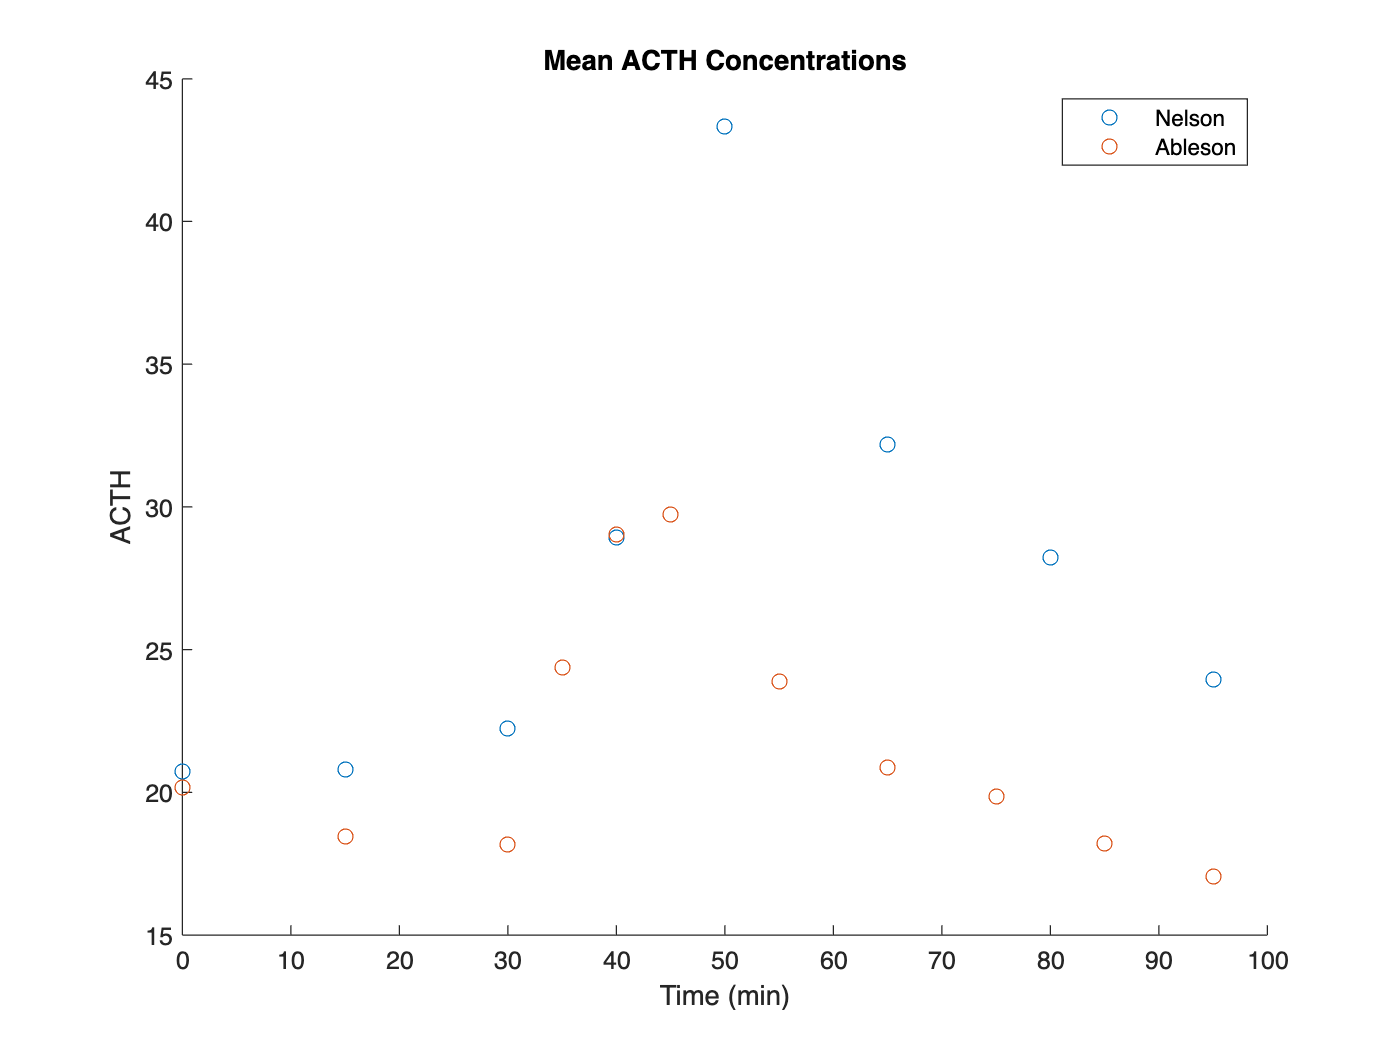

% Create scatter of selected data
hold on
scatter(MeanACTH(1:8,:),"Time_min_","NelsonFullMean","DisplayName","Nelson");
scatter(MeanACTH, 'AblesonTimes', 'AblesonFullMean', 'DisplayName','Ableson');
% Add xlabel, ylabel, title, and legend
xlabel("Time (min)")
ylabel("ACTH")
title("Mean ACTH Concentrations")
legend

clf('reset')

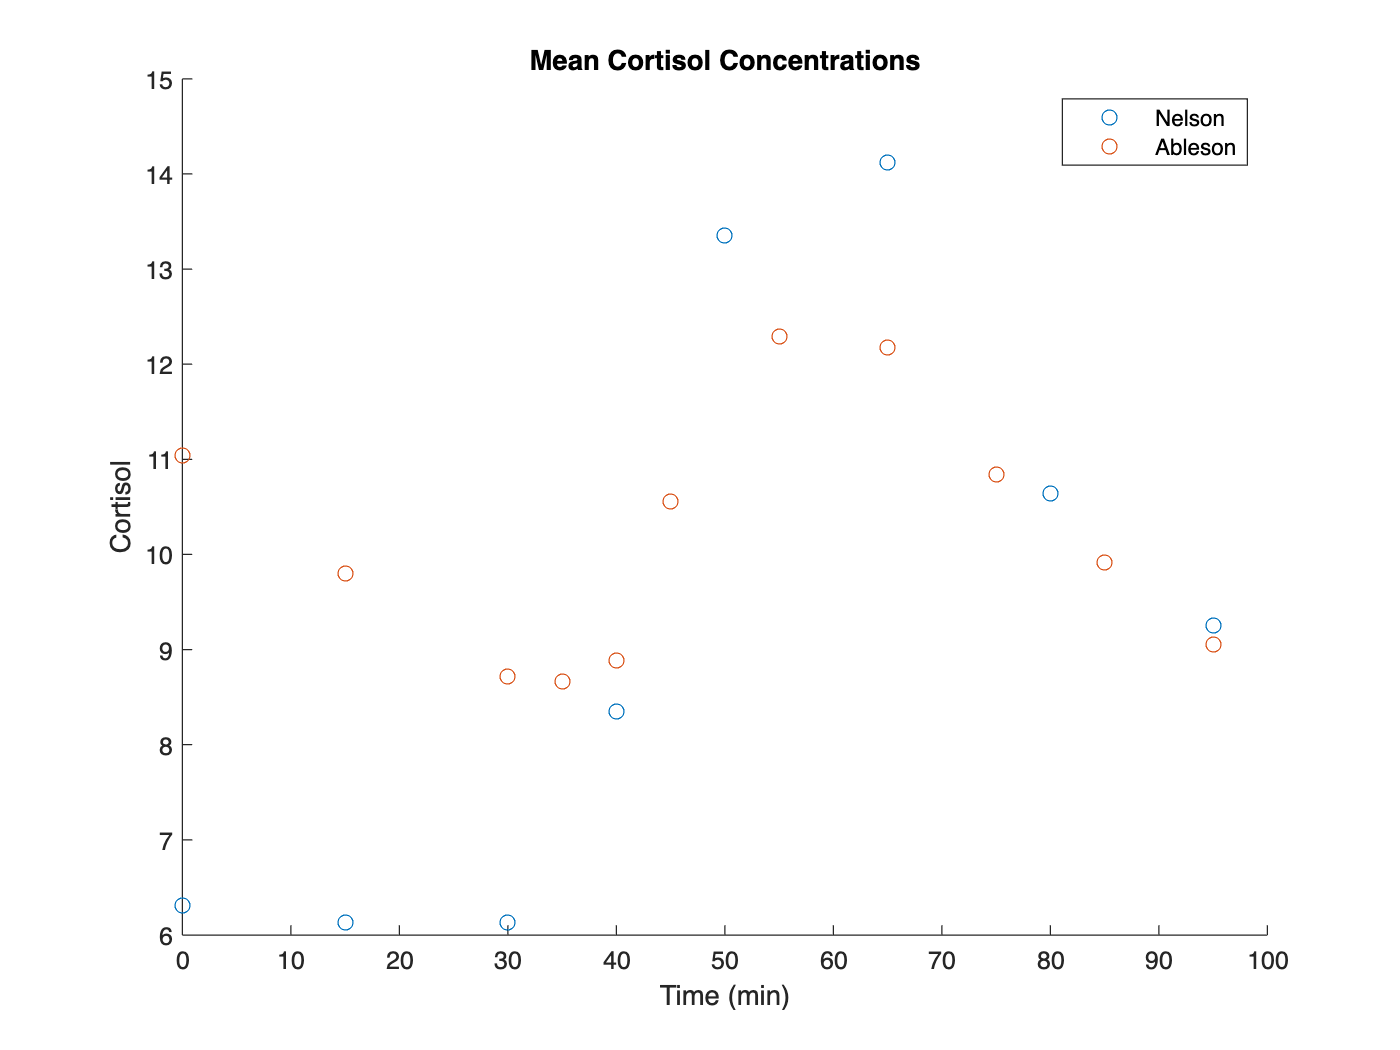

% Create scatter of selected data
hold on
scatter(MeanCortisol(1:8,:),"Time_min_","NelsonFullMean","DisplayName","Nelson");
scatter(MeanCortisol, 'AblesonTimes', 'AblesonFullMean', 'DisplayName','Ableson');
% Add xlabel, ylabel, title, and legend
xlabel("Time (min)")
ylabel("Cortisol")
title("Mean Cortisol Concentrations")
legend

clf('reset')

#### Control vs MDD (Full Pop)

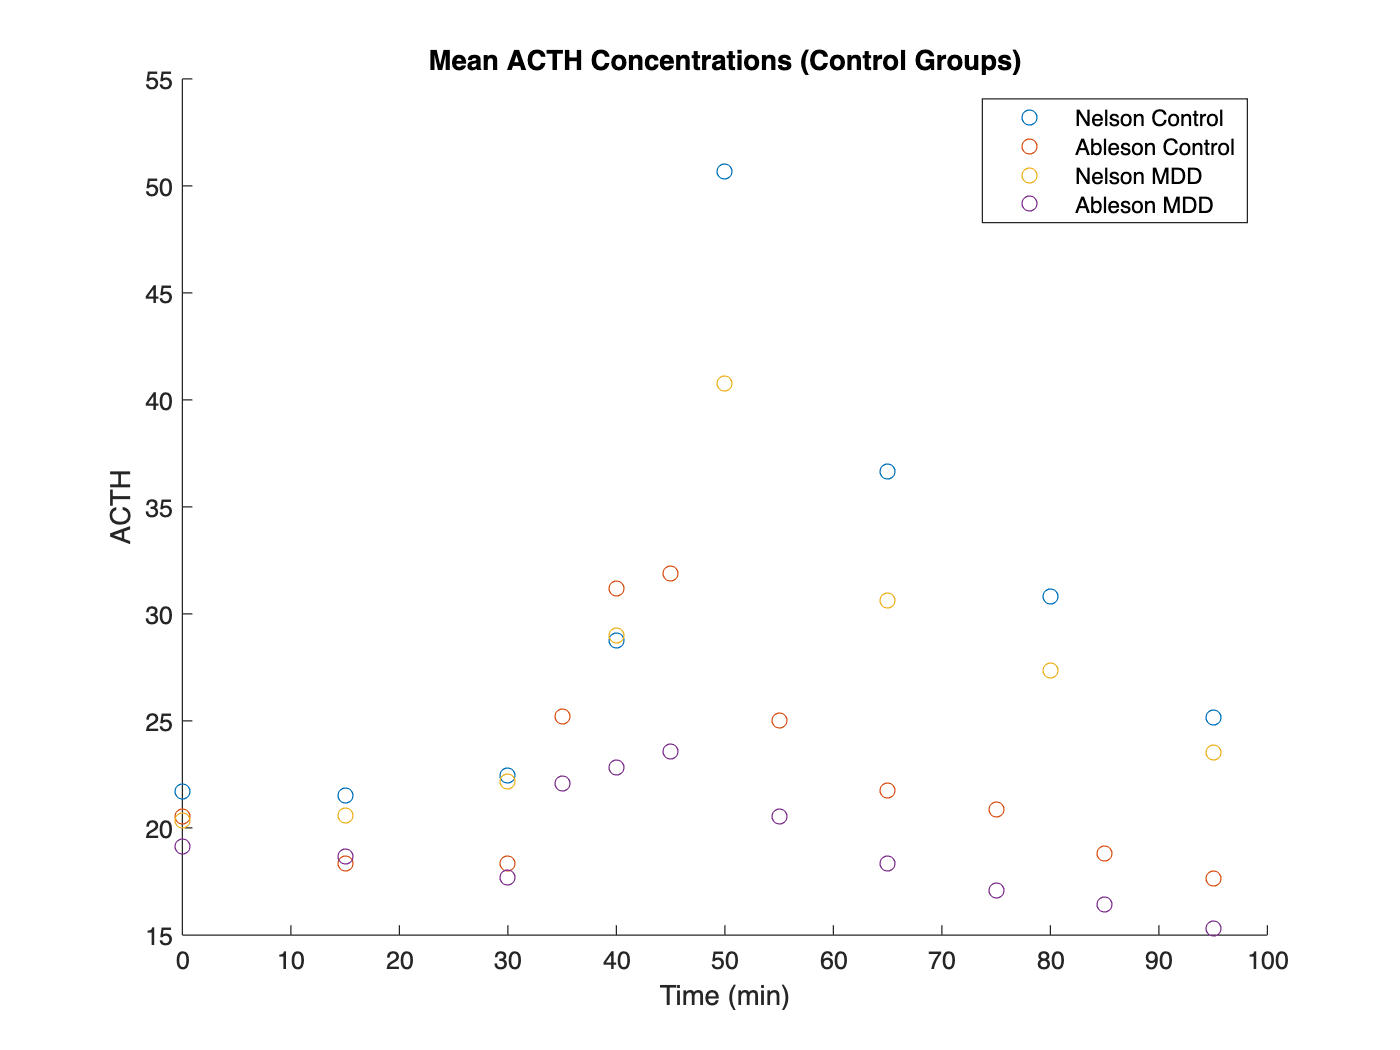

% Create scatter of selected data
hold on
scatter(MeanACTH(1:8,:),"Time_min_","NelsonControlMean","DisplayName","Nelson Control");
scatter(MeanACTH, 'AblesonTimes', 'AblesonControlMean', 'DisplayName','Ableson Control');
scatter(MeanACTH(1:8,:), 'Time_min_', 'NelsonMDDMean', 'DisplayName', 'Nelson MDD');
scatter(MeanACTH, 'AblesonTimes', 'AblesonMDDMean', 'DisplayName', 'Ableson MDD');

% Add xlabel, ylabel, title, and legend
xlabel("Time (min)")
ylabel("ACTH")
title("Mean ACTH Concentrations (Control Groups)")
legend

clf('reset')

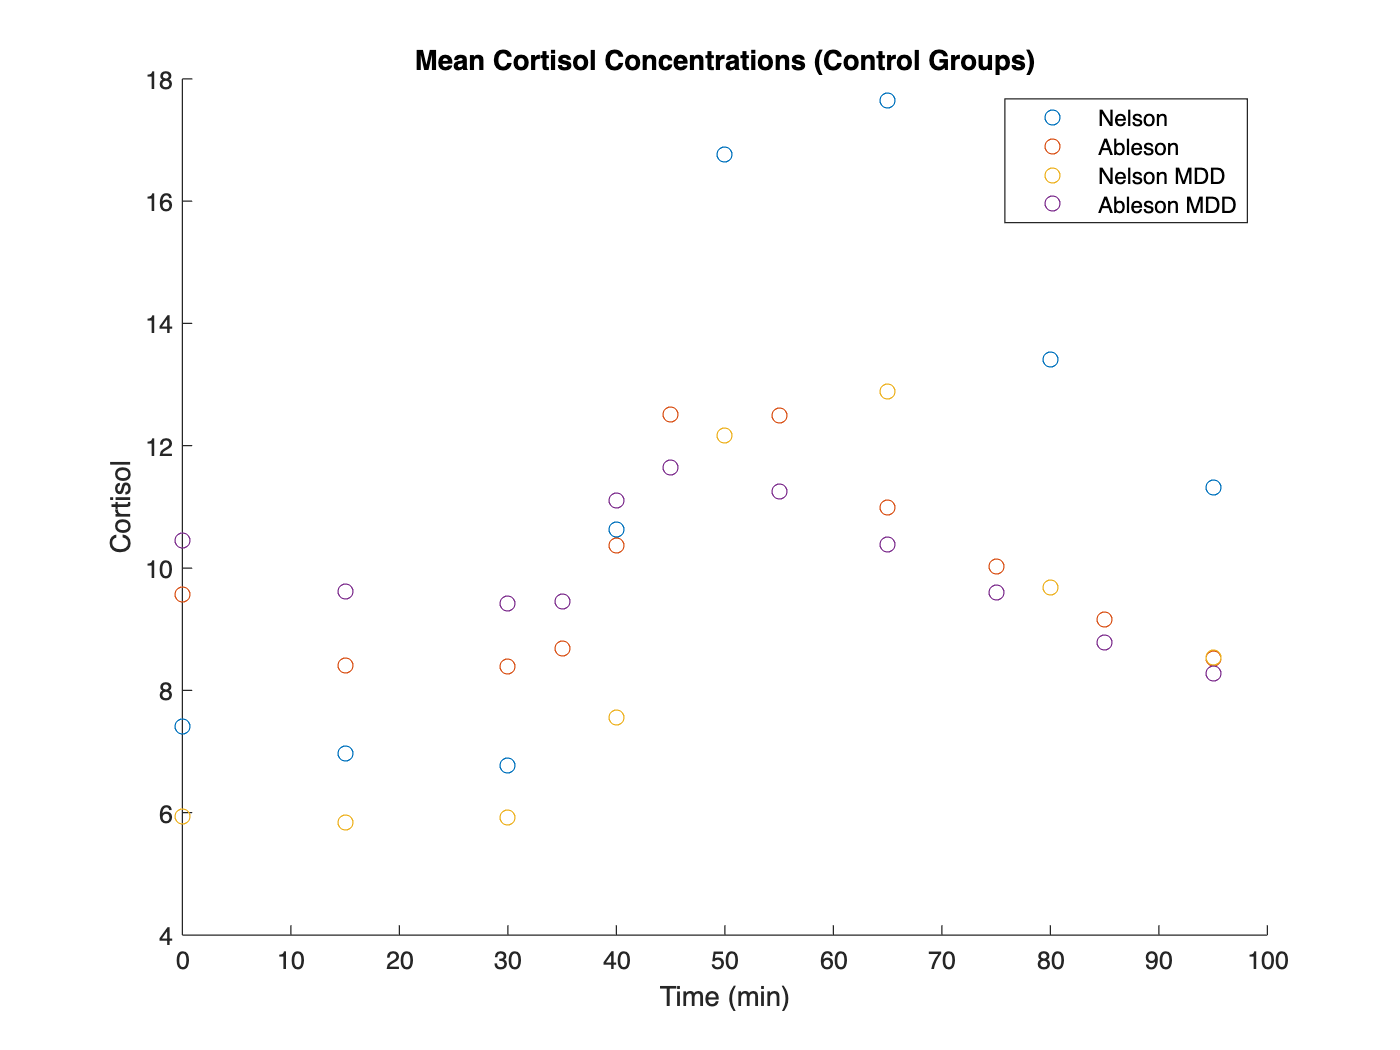

% Create scatter of selected data
hold on
scatter(MeanCortisol(1:8,:),"Time_min_","NelsonControlMean","DisplayName","Nelson");
scatter(MeanCortisol, 'AblesonTimes', 'AblesonControlMean', 'DisplayName','Ableson');
scatter(MeanCortisol(1:8,:), 'Time_min_', 'NelsonMDDMean', 'DisplayName', 'Nelson MDD');
scatter(MeanCortisol, 'AblesonTimes', 'AblesonMDDMean', 'DisplayName', 'Ableson MDD');
% Add xlabel, ylabel, title, and legend
xlabel("Time (min)")
ylabel("Cortisol")
title("Mean Cortisol Concentrations (Control Groups)")
legend

clf('reset')

#### Control vs Atypical

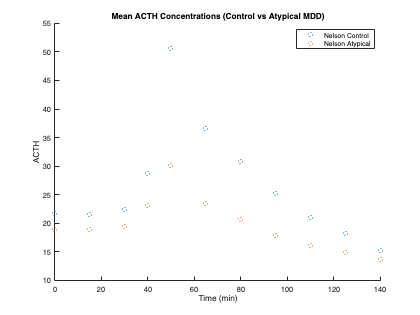

% Create scatter of selected data
hold on
scatter(MeanACTH,"Time_min_","NelsonControlMean","DisplayName","Nelson Control");
scatter(atypical_mean, 'Time_min_', 'ACTH', 'DisplayName', 'Nelson Atypical');

% Add xlabel, ylabel, title, and legend
xlabel("Time (min)")
ylabel("ACTH")
title("Mean ACTH Concentrations (Control vs Atypical MDD)")
legend

clf('reset')

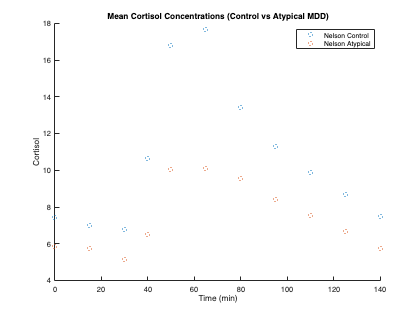

% Create scatter of selected data
hold on
scatter(MeanCortisol,"Time_min_","NelsonControlMean","DisplayName","Nelson Control");
scatter(atypical_mean, 'Time_min_', 'Cortisol', 'DisplayName', 'Nelson Atypical');
% Add xlabel, ylabel, title, and legend
xlabel("Time (min)")
ylabel("Cortisol")
title("Mean Cortisol Concentrations (Control vs Atypical MDD)")
legend

clf('reset')

#### Control vs Melancholic

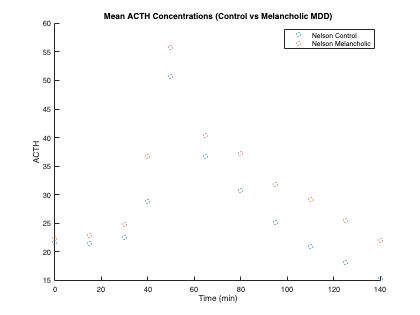

% Create scatter of selected data
hold on
scatter(MeanACTH,"Time_min_","NelsonControlMean","DisplayName","Nelson Control");
scatter(melancholic_mean, 'Time_min_', 'ACTH', 'DisplayName', 'Nelson Melancholic');

% Add xlabel, ylabel, title, and legend
xlabel("Time (min)")
ylabel("ACTH")
title("Mean ACTH Concentrations (Control vs Melancholic MDD)")
legend

clf('reset')

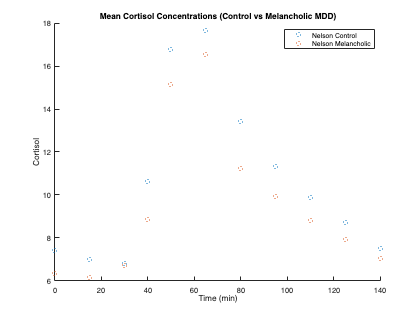

% Create scatter of selected data
hold on
scatter(MeanCortisol,"Time_min_","NelsonControlMean","DisplayName","Nelson Control");
scatter(melancholic_mean, 'Time_min_', 'Cortisol', 'DisplayName', 'Nelson Melancholic');
% Add xlabel, ylabel, title, and legend
xlabel("Time (min)")
ylabel("Cortisol")
title("Mean Cortisol Concentrations (Control vs Melancholic MDD)")
legend

clf('reset')

#### Control vs Neither

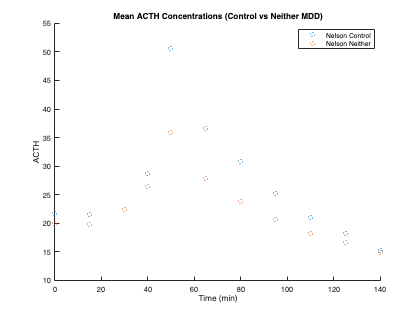

% Create scatter of selected data
hold on
scatter(MeanACTH,"Time_min_","NelsonControlMean","DisplayName","Nelson Control");
scatter(neither_mean, 'Time_min_', 'ACTH', 'DisplayName', 'Nelson Neither');

% Add xlabel, ylabel, title, and legend
xlabel("Time (min)")
ylabel("ACTH")
title("Mean ACTH Concentrations (Control vs Neither MDD)")
legend

clf('reset')

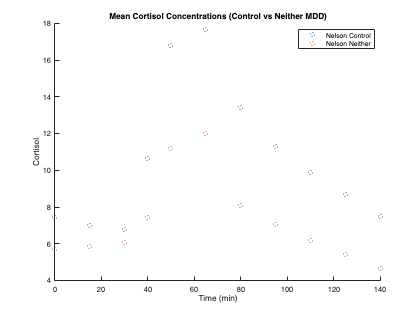

% Create scatter of selected data
hold on
scatter(MeanCortisol,"Time_min_","NelsonControlMean","DisplayName","Nelson Control");
scatter(neither_mean, 'Time_min_', 'Cortisol', 'DisplayName', 'Nelson Neither');
% Add xlabel, ylabel, title, and legend
xlabel("Time (min)")
ylabel("Cortisol")
title("Mean Cortisol Concentrations (Control vs Neither MDD)")
legend

clf('reset')